## Big Springs - Test Data 

Correct Objects 

BSCorrect = detectImportOptions("fduro\Documents\SDU\Bachelor\TestData\Big Springs\BB-BigSprings-Correct.csv")

BSCorrect =   DelimitedTextImportOptions with properties:

   Format Properties:
                    Delimiter: {','}
                   Whitespace: '\b\t '
                   LineEnding: {'\n'  '\r'  '\r\n'}
                 CommentStyle: {}
    ConsecutiveDelimitersRule: 'split'
        LeadingDelimitersRule: 'keep'
       TrailingDelimitersRule: 'ignore'
                EmptyLineRule: 'skip'
                     Encoding: 'UTF-8'

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'
             ExtraColumnsRule: 'addvars'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'LapNr', 'Roi1', 'x1' ... and 18 more}
                VariableTypes: {'double', 'char', 'double' ... and 18 more}
        SelectedVariab

BSCorrect.SelectedVariableNames = {'x1', 'y1', 'w1','h1','x2', 'y2', 'w2','h2','x3', 'y3', 'w3','h3', 'x4', 'y4', 'w4','h4'};
Correct = readtable('fduro\Documents\SDU\Bachelor\TestData\Big Springs\BB-BigSprings-Correct.csv', BSCorrect);
Correct(1:50,:)

ans = 50×16 table
    x1    y1    w1    h1    x2    y2    w2    h2    x3    y3    w3    h3    x4    y4    w4    h4
    __    __    __    __    __    __    __    __    __    __    __    __    __    __    __    __

    13    7     28    90    13    9     29    86    16    16    26    90    12    15    28    85
    13    7     28    90    13    9     29    86    16    16    26    90    12    15    29    85
    13    7     28    90    13    9     29    86 


%Make Data vectors (Concatenate ROIs)
wCorrect = [Correct.w1; Correct.w2; Correct.w3; Correct.w4];
hCorrect = [Correct.h1; Correct.h2; Correct.h3; Correct.h4];

%Mean & StdDev 
meanW_Correct = mean(wCorrect)

meanW_Correct = 27.6800

stdW_Correct = std(wCorrect)

stdW_Correct = 1.2431

meanH_Correct = mean(hCorrect)

meanH_Correct = 87.3550

stdH_Correct = std(hCorrect)

stdH_Correct = 1.6131

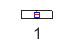


%Boxplot
boxplot(wCorrect)

#### Control Data (empty ROIs)

BSControl = detectImportOptions("fduro\Documents\SDU\Bachelor\TestData\Big Springs\BB-BigSprings-Control.csv");
BSControl.SelectedVariableNames = {'x1','y1','w1','h1','x2', 'y2', 'w2','h2','x3', 'y3', 'w3','h3', 'x4', 'y4', 'w4','h4'};
Control = readtable('fduro\Documents\SDU\Bachelor\TestData\Big Springs\BB-BigSprings-Control.csv',BSControl);
Control(1:10,:)

ans = 10×16 table
    x1    y1     w1    h1    x2    y2     w2    h2    x3    y3    w3    h3    x4    y4    w4    h4
    __    ___    __    __    __    ___    __    __    __    __    __    __    __    __    __    __

    46    101    6     12    12    101     4    7     23    98    6     16    24    89    5     16
    46    101    6     12     8     99    45    9     21    98    8     16    24    88    5     17
    46    101    6     12     9     99   


%Make Data vectors (Concatenate ROIs)
wControl = [Control.w1; Control.w2; Control.w3; Control.w4];
hControl = [Control.h1; Control.h2; Control.h3; Control.h4];

% Mean & StdDev for all four rois together
meanW_Control = mean(wControl)

meanW_Control = 8.1000

stdW_Control = std(wControl)

stdW_Control = 7.6117

meanH_Control = mean(hControl)

meanH_Control = 13.0750

stdH_Control = std(hControl)

stdH_Control = 3.4744

#### Malfunctioned Objects 

BSMalfunction = detectImportOptions("fduro\Documents\SDU\Bachelor\TestData\Big Springs\BB-BigSprings-Malfunction.csv");
BSMalfunction.SelectedVariableNames = {'x1','y1','w1','h1','x2', 'y2', 'w2','h2','x3', 'y3', 'w3','h3', 'x4', 'y4', 'w4','h4'};
Malfunction = readtable('fduro\Documents\SDU\Bachelor\TestData\Big Springs\BB-BigSprings-Malfunction.csv',BSMalfunction);
Malfunction(1:10,:)

ans = 10×16 table
    x1    y1    w1    h1    x2    y2     w2    h2    x3    y3    w3    h3    x4    y4    w4    h4
    __    __    __    __    __    ___    __    __    __    __    __    __    __    __    __    __

    9     22    26    75    56    108    7     21    21    55    25    62    14    13    24    85
    9     22    26    75    56    108    7     21    21    54    25    63    13    13    25    84
    9     22    26    75    56    108    7   


%Make Data vectors (Concatenate ROIs)
wMal = [Malfunction.w1; Malfunction.w2; Malfunction.w3; Malfunction.w4]

wMal =     26
    26
    26
    26
    26
    26
    26
    26
    26
    26


hMal = [Malfunction.h1; Malfunction.h2; Malfunction.h3; Malfunction.h4]

hMal =     75
    75
    75
    75
    75
    75
    75
    75
    75
    75



% Mean & StdDev for all four rois together
meanW_Mal = mean(wMal)

meanW_Mal = 20.7250

stdW_Mal = std(wMal)

stdW_Mal = 8.1208

meanH_Mal = mean(hMal)

meanH_Mal = 60.7000

stdH_Mal = std(hMal)

stdH_Mal = 24.5254

#### Light Changes

BSLight = detectImportOptions("fduro\Documents\SDU\Bachelor\TestData\Big Springs\BB-BigSprings-LightChanges.csv");
BSLight.SelectedVariableNames = {'x1','y1','w1','h1','x2', 'y2', 'w2','h2','x3', 'y3', 'w3','h3', 'x4', 'y4', 'w4','h4'};
Light = readtable('fduro\Documents\SDU\Bachelor\TestData\Big Springs\BB-BigSprings-LightChanges.csv',BSControl);
Light(1:6,:)

ans = 6×16 table
    x1    y1    w1    h1    x2    y2    w2    h2    x3    y3    w3    h3    x4    y4    w4    h4
    __    __    __    __    __    __    __    __    __    __    __    __    __    __    __    __

    4     7     27    88    7     11    28    85    8     14    28    86    10    13    28    85
    5     7     26    88    7     10    28    86    8     14    28    86    10    13    28    85
    5     7     26    88    7     10    28    86  


%Make Data vectors (Concatenate ROIs)
wLight = [Light.w1; Light.w2; Light.w3; Light.w4];
hLight = [Light.h1; Light.h2; Light.h3; Light.h4];

% Mean & StdDev for all four rois together
meanW_Light = mean(wLight)

meanW_Light = 27.4583

stdW_Light = std(wLight)

stdW_Light = 0.8836

meanH_Light = mean(hLight)

meanH_Light = 86.5000

stdH_Light = std(hLight)

stdH_Light = 1.0632

### Histograms

#### All Data 

Width

% Hist_W1 =histogram(Correct.w1,FaceColor = [0 0.5 0.5]);
% hold on
% Hist_W2 =histogram(Correct.w2,FaceColor = [0 0.5 0.6]);
% Hist_W3 =histogram(Correct.w3,FaceColor = [0 0.5 0.7]);
% Hist_W4 =histogram(Correct.w4,FaceColor = [0 0.5 0.8]);
% 
% Hist_WC =histogram(wControl,FaceColor = [0 0.9 0]);
% Hist_WL = histogram(wLight,FaceColor = [0.9 0.1 0]);
% Hist_WM =histogram(wMal,FaceColor = [0.5 0.1 0.5]);
% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Control', 'Light Changes', 'Malfunctions')

Height

% Hist_H1 =histogram(Correct.h1,FaceColor = [0 0.5 0.5]);
% hold on
% Hist_H2 =histogram(Correct.h2,FaceColor = [0 0.5 0.6]);
% Hist_H3 =histogram(Correct.h3,FaceColor = [0 0.5 0.7]);
% Hist_H4 =histogram(Correct.h4,FaceColor = [0 0.5 0.8]);
% 
% Hist_HC =histogram(hControl,FaceColor = [0 0.9 0]);
% Hist_HL = histogram(hLight,FaceColor = [0.9 0.1 0]);
% Hist_HM =histogram(hMal,70,FaceColor = [0.5 0.1 0.5]);
% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Control', 'Light Changes', 'Malfunctions')

#### Correct & Empty

Width

% Hist_W1 =histogram(Correct.w1,FaceColor = [0 0.5 0.5]);
% hold on
% Hist_W2 =histogram(Correct.w2,FaceColor = [0 0.5 0.6]);
% Hist_W3 =histogram(Correct.w3,FaceColor = [0 0.5 0.7]);
% Hist_W4 =histogram(Correct.w4,FaceColor = [0 0.5 0.8]);
% 
% Hist_WC =histogram(wControl,FaceColor = [0 0.9 0]);
% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Empty')

Height

% Hist_H1 =histogram(Correct.h1,FaceColor = [0 0.5 0.5]);
% hold on
% Hist_H2 =histogram(Correct.h2,FaceColor = [0 0.5 0.6]);
% Hist_H3 =histogram(Correct.h3,FaceColor = [0 0.5 0.7]);
% Hist_H4 =histogram(Correct.h4,FaceColor = [0 0.5 0.8]);
% 
% Hist_HC =histogram(hControl,FaceColor = [0 0.9 0]);
% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Empty')

#### Correct & Malfunctions

Correct Width

% Hist_W1 =histogram(Correct.w1,FaceColor = [0 0.5 0.5]);
% hold on
% Hist_W2 =histogram(Correct.w2,FaceColor = [0 0.5 0.6]);
% Hist_W3 =histogram(Correct.w3,FaceColor = [0 0.5 0.7]);
% Hist_W4 =histogram(Correct.w4,FaceColor = [0 0.5 0.8]);

Correct Height

% Hist_H1 =histogram(Correct.h1,FaceColor = [0 0.5 0.5]);
% hold on
% Hist_H2 =histogram(Correct.h2,FaceColor = [0 0.5 0.6]);
% Hist_H3 =histogram(Correct.h3,FaceColor = [0 0.5 0.7]);
% Hist_H4 =histogram(Correct.h4,FaceColor = [0 0.5 0.8]);

**All malfunctions in one**

Width

% Hist_WM =histogram(wMal,FaceColor = [0.5 0.1 0.5]);
% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Malfunctions')

Height

% Hist_HM =histogram(hMal,70,FaceColor = [0.5 0.1 0.5]);
% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Malfunctions')

**Malfunctions devided after ROIs**

Width

% Hist_WM1 =histogram(Malfunction.w1,FaceColor = [0.0 0 0.5]);
% Hist_WM2 =histogram(Malfunction.w2,FaceColor = [0.25 0 0.5]);
% Hist_WM3 =histogram(Malfunction.w3,FaceColor = [0.5 0 0.5]);
% Hist_WM4 =histogram(Malfunction.w4,FaceColor = [1.0 0 0.5]);

% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Malfunctions-ROI1','Malfunctions-ROI2','Malfunctions-ROI3','Malfunctions-ROI4')

Height

% Hist_HM1 =histogram(Malfunction.h1,FaceColor = [0.0 0 0.5]);
% Hist_HM2 =histogram(Malfunction.h2,FaceColor = [0.25 0 0.5]);
% Hist_HM3 =histogram(Malfunction.h3,FaceColor = [0.5 0 0.5]);
% Hist_HM4 =histogram(Malfunction.h4,FaceColor = [1.0 0 0.5]);
% 
% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Malfunctions-ROI1','Malfunctions-ROI2','Malfunctions-ROI3','Malfunctions-ROI4')

**Single Malfunctions **

% Hist_WM1 =histogram(Malfunction.w1,FaceColor = [1.0 0 0.5]);
% Hist_WM2 =histogram(Malfunction.w2,FaceColor = [1.0 0 0.5]);
% Hist_WM3 =histogram(Malfunction.w3,FaceColor = [1.0 0 0.5]);
% Hist_WM4 =histogram(Malfunction.w4,FaceColor = [1.0 0 0.5]);
% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Malfunctions-ROI1')

#### Correct & Light Changes

Width

% Hist_W1 =histogram(Correct.w1,FaceColor = [0 0.5 0.5]);
% hold on
% Hist_W2 =histogram(Correct.w2,FaceColor = [0 0.5 0.6]);
% Hist_W3 =histogram(Correct.w3,FaceColor = [0 0.5 0.7]);
% Hist_W4 =histogram(Correct.w4,FaceColor = [0 0.5 0.8]);
% 
% Hist_WL = histogram(wLight,FaceColor = [0.9 0.1 0]);
% legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Light Changes')

Height

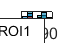

Hist_H1 =histogram(Correct.h1,FaceColor = [0 0.5 0.5]);
hold on
Hist_H2 =histogram(Correct.h2,FaceColor = [0 0.5 0.6]);
Hist_H3 =histogram(Correct.h3,FaceColor = [0 0.5 0.7]);
Hist_H4 =histogram(Correct.h4,FaceColor = [0 0.5 0.8]);

Hist_HL = histogram(hLight,FaceColor = [0.9 0.1 0]);
legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Light Changes')